# Diabetes Prediction Using ANN

clear
clc

#### Loading dataset

diabetes = readtable("diabetes.csv");

The dataset contains 768 data samples. Each sample includes values of "pregnancies", "glucose", "blood pressure", "skin thickness", "insulin", "BMI", "diabetes pedigree function", "age" and the diabetes diagnosis (binary).

head(diabetes)

    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66               23         

This LiveScript is to build and train an ANN that predict the diabete diagnosis, given "pregnancies", "glucose", "blood pressure", "skin thickness", "insulin", "BMI", "diabetes pedigree function" and "age".

#### Rearanging the dataset

rng('default')
% Convert output into categorical
labelName = "Outcome";
diabetes = convertvars(diabetes,labelName,'categorical');
head(diabetes)

    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66               23         

% Spliting the dataset
[trainInd,valInd,testInd] = dividerand(size(diabetes,1), 0.7, 0.15, 0.15);
tblTrain = diabetes(trainInd,:);  % Extracting training sample
tblValid = diabetes(valInd,:); % Extracting validation sample
tblTest = diabetes(testInd,:); % Extracting testing sample
% Number of classes
numClasses = 2;

#### Constructing a neural network

layers = [
    featureInputLayer(size(tblTrain,2)-1,"Normalization","rescale-zero-one")
    fullyConnectedLayer(40)         % increased hidden layer neurons
    reluLayer           % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(40)         % additional hidden layer
    reluLayer           % ReLU activation func. (not a new layer of neurons)
    fullyConnectedLayer(numClasses) % Output layer: # output dim.
    softmaxLayer                    % softmax layer for classification
    classificationLayer("Name","output")];

#### Configuring the training options

options = trainingOptions('adam', ...   % using adam optimizer
    'MaxEpochs',6000, ...               % number of epochs of training
    'MiniBatchSize', size(tblTrain,1), ... % batch training
    'L2Regularization', 1e-3, ...       % L2 Regularization
    'Shuffle','every-epoch', ...    % shuffling the training samples
    'ValidationFrequency',40, ...   % Computing validation accuracy every 40 epoch
    'ValidationPatience',20, ...    % Stop the training if acc not improve for 20 valid
    'ValidationData',tblValid, ... % Validation set
    'Plots','training-progress', ...    % visualizing the training process
    'ExecutionEnvironment', 'cpu', ...  % training on CPU
    'Verbose',false); % hide notice while training


#### Training the neural network

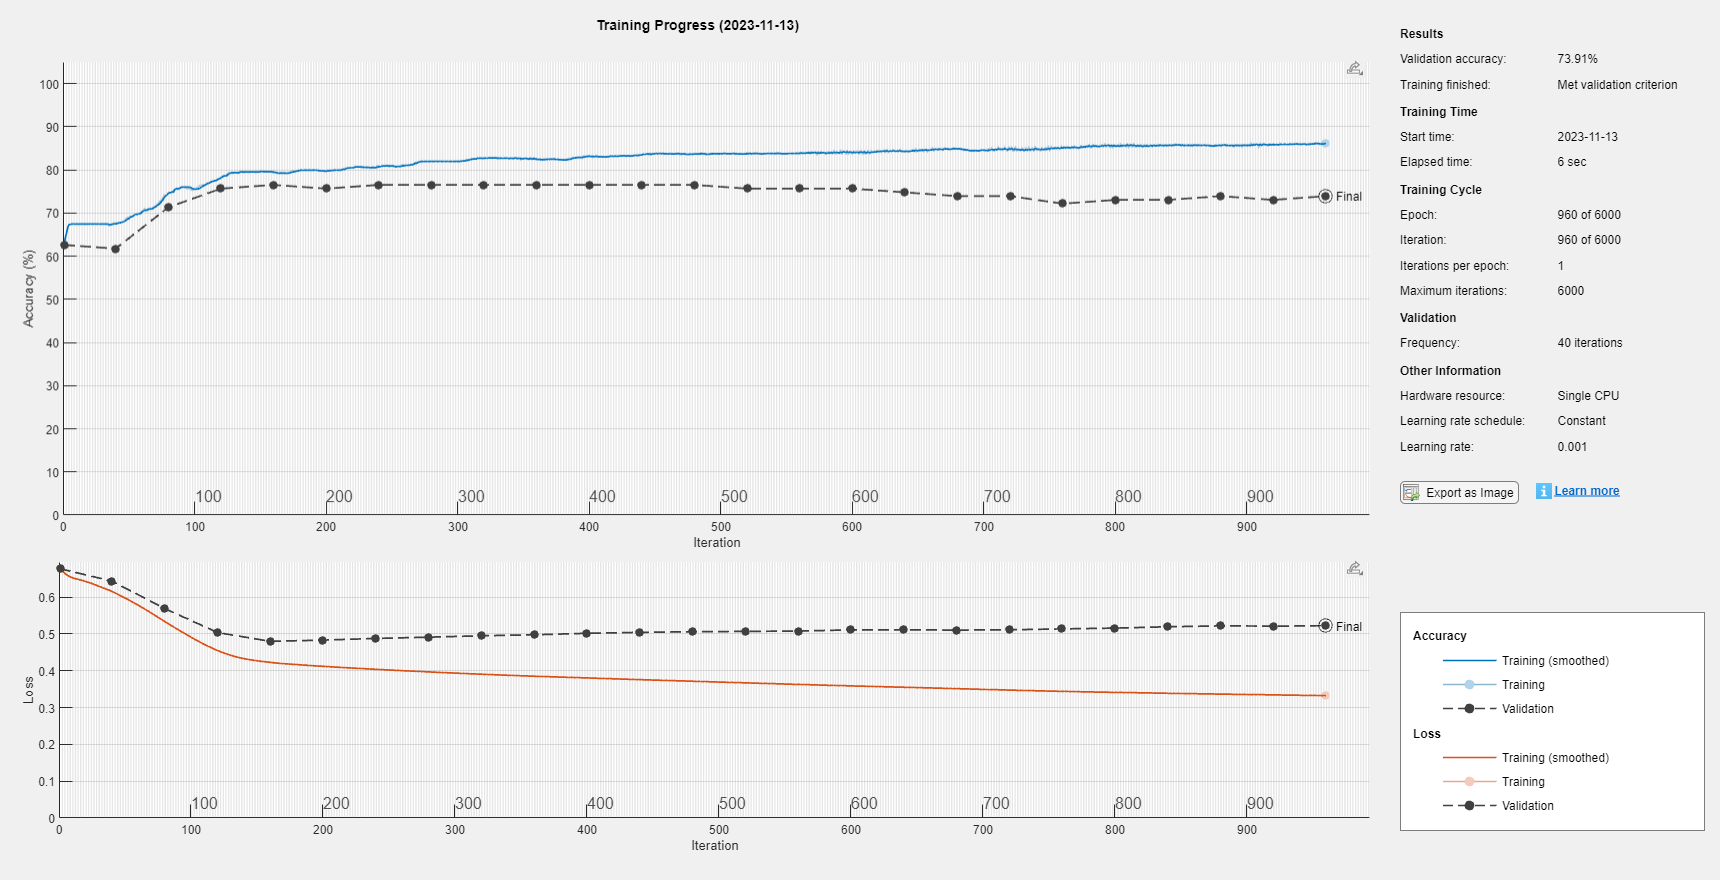

net = trainNetwork(tblTrain, layers, options);

% Predicting test set
y_pred = predict(net, tblTest,'ReturnCategorical',1)

y_pred = 115×1 categorical array
     0 
     0 
     1 
     0 
     1 
     0 
     0 
     0 
     1 
     0 
     0 
     1 
     1 
     0 
     0 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     1 
     0 
     0 
     1 
     0 
     0 
     0 
     1 


% number of correct predictions
acc_temp = nnz(y_pred(:,1) == tblTest.Outcome); 
acc = acc_temp ./ size(tblTest.Outcome, 1)

acc = 0.7043